## Naïve Bayes Code Tests

### Analysis from a Naïve Bayes perspective dataset NOT normalised


clear
clc
clf
close all
% loads the letter dataset into letterDatasetNormalised and
% letterDatasetNotNormalised
load letterDatasetClass.mat

letterDataset = letterDatasetNotNormalised;
[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);
% start timer
startTime = cputime

startTime = 2.2738e+04

% get a default class
nBayes = NBayesClass.getDefaultInstance(letterDataset);
nBayes.nBayesModel.Prior

ans =     0.0391    0.0381    0.0381    0.0399    0.0384    0.0378    0.0393    0.0361    0.0379    0.0361    0.0367    0.0384    0.0396    0.0383    0.0382    0.0407    0.0386    0.0375    0.0381    0.0413    0.0404    0.0393    0.0377    0.0387    0.0394    0.0366


[dfltLTrainLoss, dfltTestLoss] = nBayes.getModelLoss();
nBayes.setPriorDistributionEmpirical();
nBayes.nBayesModel.Prior

ans =     0.0413    0.0379    0.0399    0.0383    0.0393    0.0391    0.0396    0.0387    0.0382    0.0375    0.0381    0.0361    0.0381    0.0361    0.0384    0.0381    0.0384    0.0394    0.0386    0.0407    0.0393    0.0377    0.0404    0.0378    0.0366    0.0368


[empTrainLoss, emptTestLoss] = nBayes.getModelLoss();
fprintf("Default Training Loss:   %0.02f Test Loss %0.02f\n", dfltLTrainLoss, dfltTestLoss);

Default Training Loss:   0.35 Test Loss 0.37


fprintf("Empirical Training Loss: %0.02f Test Loss %0.02f\n", empTrainLoss, emptTestLoss);

Empirical Training Loss: 0.35 Test Loss 0.37


Set prior distribution to an empirical distribution

model = nBayes.setPriorDistributionEmpirical();
cvModel = crossval(model);
modelLoss = kfoldLoss(cvModel);
crossValModel = crossval(model);
fprintf("KFold Loss:: %0.02f\n", kfoldLoss(crossValModel));

KFold Loss:: 0.36


[predicted, score] = resubPredict(model);
confusionMat = confusionchart(categorical(Y), predicted);

Look at the classifiers that have been setup for each attribute. There are 16 of them, each one configurable.

disp(model.DistributionNames(:,:));

  Columns 1 through 6

    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}

  Columns 7 through 12

    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}

  Columns 13 through 16

    {'normal'}    {'normal'}    {'normal'}    {'normal'}



[trainingLoss, testLoss] = nBayes.getModelLoss();
fprintf("Training loss: %0.02f Test loss: %0.02f, normalised dataset: %d\n", trainingLoss, testLoss, nBayes.dataset.isNormalised);

Training loss: 0.35 Test loss: 0.37, normalised dataset: 0


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.02f", totalTime);

Total cpu time (seconds): 6.69

#### Try Optimization

% start timer
startTime = cputime

startTime = 2.2745e+04

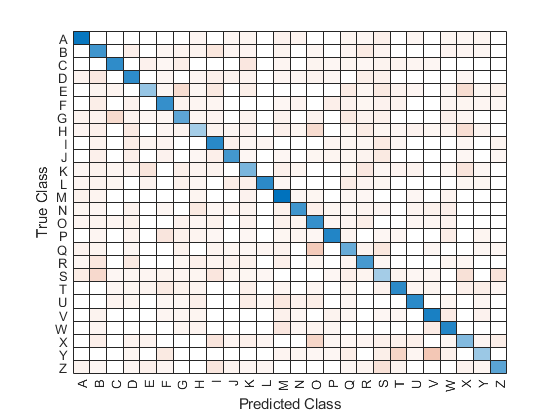

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.33644 |      69.639 |     0.33644 |     0.33644 |       kernel |        1.287 |


|    2 | Accept |     0.35725 |     0.40532 |     0.33644 |     0.34644 |       normal |            - |


|    3 | Accept |     0.35725 |     0.40265 |     0.33644 |     0.33644 |       normal |            - |


|    4 | Accept |     0.51019 |      68.495 |     0.33644 |     0.33644 |       kernel |       8.6162 |


|    5 | Best   |     0.25006 |       41.79 |     0.25006 |     0.25007 |       kernel |      0.30805 |


|    6 | Best   |     0.24919 |      41.656 |     0.24919 |     0.24914 |       kernel |      0.25009 |


|    7 | Accept |     0.24919 |      42.392 |     0.24919 |     0.24916 |       kernel |      0.25013 |


|    8 | Accept |     0.24919 |      41.944 |     0.24919 |     0.24917 |       kernel |      0.25022 |


|    9 | Accept |     0.24919 |      41.929 |     0.24919 |     0.24917 |       kernel |      0.26337 |


|   10 | Accept |     0.24919 |      41.493 |     0.24919 |     0.24917 |       kernel |      0.25043 |


|   11 | Accept |     0.27044 |       53.86 |     0.24919 |     0.24922 |       kernel |      0.61428 |


|   12 | Accept |     0.61375 |      66.385 |     0.24919 |      0.2492 |       kernel |       14.998 |


|   13 | Accept |     0.24938 |      41.998 |     0.24919 |     0.24924 |       kernel |      0.27578 |


|   14 | Accept |     0.44525 |      73.037 |     0.24919 |     0.24919 |       kernel |       3.1633 |


|   15 | Accept |     0.24931 |      42.033 |     0.24919 |      0.2492 |       kernel |      0.26992 |


|   16 | Accept |     0.25769 |      43.238 |     0.24919 |     0.24921 |       kernel |      0.44953 |


|   17 | Accept |     0.29875 |      62.542 |     0.24919 |     0.24921 |       kernel |      0.87686 |


|   18 | Accept |     0.48094 |      74.627 |     0.24919 |     0.24921 |       kernel |       5.1232 |


|   19 | Accept |      0.2525 |       42.33 |     0.24919 |     0.24921 |       kernel |      0.37089 |


|   20 | Accept |     0.39281 |       72.82 |     0.24919 |     0.24921 |       kernel |       1.9431 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|   21 | Accept |     0.25031 |      42.648 |     0.24919 |     0.24919 |       kernel |      0.33501 |


|   22 | Accept |     0.26306 |      54.454 |     0.24919 |     0.24919 |       kernel |      0.52137 |


|   23 | Best   |     0.24913 |      42.325 |     0.24913 |     0.24918 |       kernel |      0.25916 |


|   24 | Accept |     0.24944 |      42.344 |     0.24913 |     0.24918 |       kernel |      0.28773 |


|   25 | Accept |     0.24913 |      42.004 |     0.24913 |     0.24918 |       kernel |      0.25891 |


|   26 | Accept |     0.24913 |      42.053 |     0.24913 |     0.24917 |       kernel |       0.2586 |


|   27 | Accept |     0.54869 |      71.464 |     0.24913 |     0.24917 |       kernel |       11.674 |


|   28 | Accept |     0.28331 |      53.808 |     0.24913 |     0.24917 |       kernel |      0.72876 |


|   29 | Accept |       0.423 |      76.313 |     0.24913 |     0.24917 |       kernel |       2.4778 |


|   30 | Accept |      0.4925 |      73.611 |     0.24913 |     0.24917 |       kernel |       6.5632 |


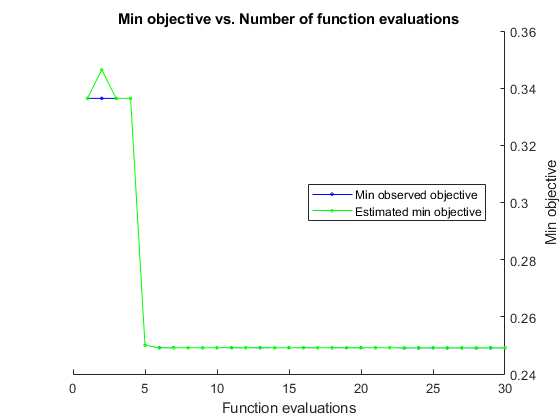

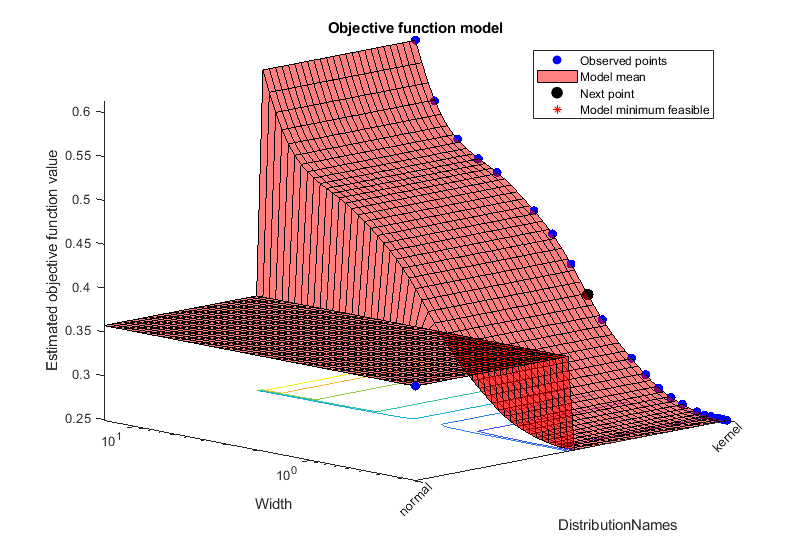


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 1527.8565 seconds
Total objective function evaluation time: 1504.0411

Best observed feasible point:
    DistributionNames     Width 
    _________________    _______

         kernel          0.25916

Observed objective function value = 0.24913
Estimated objective function value = 0.24917
Function evaluation time = 42.3252

Best estimated feasible point (according to models):
    DistributionNames     Width 
    _________________    _______

         kernel          0.25916

Estimated objective function value = 0.24917
Estimated function evaluation time = 41.7395



obj =   NBayesClass with properties:

          randomSeed: 300
               debug: 1
             dataset: [1×1 LetterDatasetClass]
         nBayesModel: [1×1 ClassificationNaiveBayes]
                   x: [16000×16 table]
                   y: [16000×1 table]
                  xt: [4000×16 table]
                  yt: [4000×1 table]
    distNamesDefault: {'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'}
     distNamesKernel: {'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'}


nBayes = NBayesClass.getDefaultInstance(letterDataset);
nBayes.fitMatlabHyperparameterOptimization();


[trainingLoss, testLoss] = nBayes.getModelLoss();
fprintf("Training loss: %0.02f Test loss: %0.02f, normalised dataset: %d\n", trainingLoss, testLoss, nBayes.dataset.isNormalised);

Training loss: 0.23 Test loss: 0.25, normalised dataset: 0



endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.02f", totalTime);

Total cpu time (seconds): 7252.95

### Try 'normal' distribution on normalised dataset

clear
clc
clf
close all
% loads the letter dataset into letterDatasetNormalised and
% letterDatasetNotNormalised
load letterDatasetClass.mat
letterDataset = letterDatasetNormalised;
[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);
% start timer
startTime = cputime

startTime = 2.9999e+04

nBayes = NBayesClass.getDefaultInstance(letterDataset);
model = nBayes.setPriorDistributionEmpirical();
cvModel = crossval(model);
modelLoss = kfoldLoss(cvModel);
crossValModel = crossval(model);
fprintf("KFold Loss:: %0.02f\n", kfoldLoss(crossValModel));

KFold Loss:: 0.36


[predicted, score] = resubPredict(model);
confusionMat = confusionchart(categorical(Y), predicted);
disp(model.DistributionNames(:,:));

  Columns 1 through 5

    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}

  Columns 6 through 10

    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}

  Columns 11 through 15

    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}

  Column 16

    {'normal'}



[trainingLoss, testLoss] = nBayes.getModelLoss();
fprintf("Training loss: %0.02f Test loss: %0.02f, normalised dataset: %d\n", trainingLoss, testLoss, nBayes.dataset.isNormalised);

Training loss: 0.35 Test loss: 0.37, normalised dataset: 1


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.02f", totalTime);

Total cpu time (seconds): 5.09

#### Try Optimization

% start timer
startTime = cputime

startTime = 3.0005e+04

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.33644 |      70.785 |     0.33644 |     0.33644 |       kernel |       0.0858 |


|    2 | Accept |     0.35725 |     0.41031 |     0.33644 |     0.34644 |       normal |            - |


|    3 | Accept |     0.35725 |     0.40377 |     0.33644 |     0.33644 |       normal |            - |


|    4 | Accept |     0.51019 |      75.877 |     0.33644 |     0.33644 |       kernel |      0.57441 |


|    5 | Best   |     0.25006 |      42.275 |     0.25006 |     0.25007 |       kernel |     0.020537 |


|    6 | Best   |     0.24919 |      42.156 |     0.24919 |     0.24914 |       kernel |     0.016673 |


|    7 | Accept |     0.24919 |      42.502 |     0.24919 |     0.24916 |       kernel |     0.016675 |


|    8 | Accept |     0.24919 |      42.125 |     0.24919 |     0.24917 |       kernel |     0.016682 |


|    9 | Accept |     0.24919 |      42.432 |     0.24919 |     0.24917 |       kernel |     0.017558 |


|   10 | Best   |     0.24913 |      42.015 |     0.24913 |     0.24916 |       kernel |     0.016708 |


|   11 | Accept |     0.27044 |      54.512 |     0.24913 |     0.24922 |       kernel |     0.040952 |


|   12 | Accept |     0.61375 |      74.426 |     0.24913 |     0.24918 |       kernel |      0.99985 |


|   13 | Accept |     0.24938 |      42.386 |     0.24913 |     0.24923 |       kernel |     0.018363 |


|   14 | Accept |     0.44525 |      74.573 |     0.24913 |     0.24918 |       kernel |      0.21089 |


|   15 | Accept |     0.24931 |      42.222 |     0.24913 |      0.2492 |       kernel |     0.017963 |


|   16 | Accept |     0.25769 |      42.556 |     0.24913 |      0.2492 |       kernel |     0.029968 |


|   17 | Accept |     0.29875 |      63.378 |     0.24913 |      0.2492 |       kernel |     0.058457 |


|   18 | Accept |     0.48094 |      72.854 |     0.24913 |      0.2492 |       kernel |      0.34155 |


|   19 | Accept |      0.2525 |      42.663 |     0.24913 |      0.2492 |       kernel |     0.024723 |


|   20 | Accept |     0.39281 |      74.821 |     0.24913 |      0.2492 |       kernel |      0.12954 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|   21 | Accept |     0.25031 |      42.363 |     0.24913 |     0.24919 |       kernel |     0.022334 |


|   22 | Accept |     0.26306 |      54.884 |     0.24913 |     0.24919 |       kernel |     0.034758 |


|   23 | Accept |     0.24913 |      43.023 |     0.24913 |     0.24918 |       kernel |     0.017277 |


|   24 | Accept |     0.24944 |      42.839 |     0.24913 |     0.24918 |       kernel |     0.019182 |


|   25 | Accept |     0.24913 |      42.736 |     0.24913 |     0.24917 |       kernel |     0.017261 |


|   26 | Accept |     0.24913 |      42.909 |     0.24913 |     0.24917 |       kernel |     0.017202 |


|   27 | Accept |     0.54869 |        71.3 |     0.24913 |     0.24917 |       kernel |       0.7783 |


|   28 | Accept |     0.28331 |      54.254 |     0.24913 |     0.24917 |       kernel |     0.048584 |


|   29 | Accept |       0.423 |      73.257 |     0.24913 |     0.24917 |       kernel |      0.16519 |


|   30 | Accept |      0.4925 |      73.277 |     0.24913 |     0.24917 |       kernel |      0.43754 |


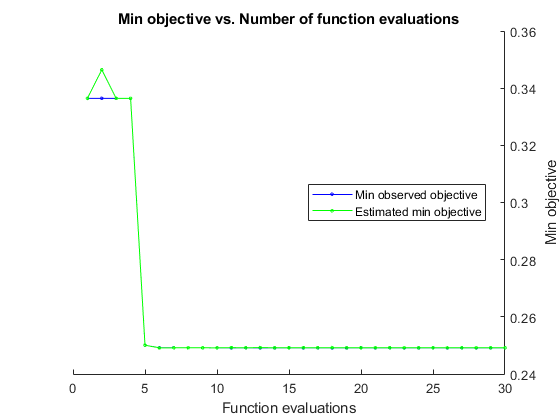

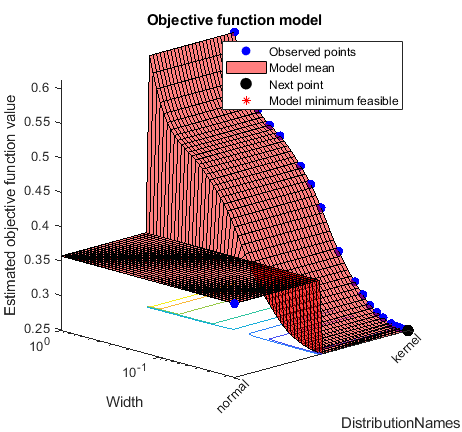


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 1548.7464 seconds
Total objective function evaluation time: 1526.2143

Best observed feasible point:
    DistributionNames     Width  
    _________________    ________

         kernel          0.016708

Observed objective function value = 0.24913
Estimated objective function value = 0.24919
Function evaluation time = 42.0148

Best estimated feasible point (according to models):
    DistributionNames     Width  
    _________________    ________

         kernel          0.017277

Estimated objective function value = 0.24917
Estimated function evaluation time = 42.2364



obj =   NBayesClass with properties:

          randomSeed: 300
               debug: 1
             dataset: [1×1 LetterDatasetClass]
         nBayesModel: [1×1 ClassificationNaiveBayes]
                   x: [16000×16 table]
                   y: [16000×1 table]
                  xt: [4000×16 table]
                  yt: [4000×1 table]
    distNamesDefault: {'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'}
     distNamesKernel: {'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'}


nBayes = NBayesClass.getDefaultInstance(letterDataset);
nBayes.fitMatlabHyperparameterOptimization();

[trainingLoss, testLoss] = nBayes.getModelLoss();
fprintf("Training loss: %0.02f Test loss: %0.02f, normalised dataset: %d\n", trainingLoss, testLoss, nBayes.dataset.isNormalised);

Training loss: 0.23 Test loss: 0.25, normalised dataset: 1


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.02f", totalTime);

Total cpu time (seconds): 7360.09

### Try 'kernel' distribution on normalised dataset

startTime = cputime

startTime = 3.7365e+04

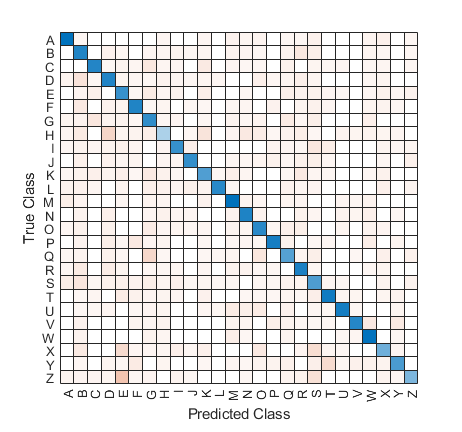

nBayes = NBayesClass.getKernelInstance(letterDataset);
model = nBayes.setPriorDistributionEmpirical();
predictions = resubPredict(model);
confusionMat = confusionchart(categorical(Y), predictions);

[trainingLoss, testLoss] = nBayes.getModelLoss();
fprintf("Training loss: %0.02f Test loss: %0.02f, normalised dataset: %d\n", trainingLoss, testLoss, nBayes.dataset.isNormalised);

Training loss: 0.30 Test loss: 0.32, normalised dataset: 1


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.02f", totalTime);

Total cpu time (seconds): 604.02

#### Try Optimization

% start timer
startTime = cputime

startTime = 3.7970e+04

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.33644 |      71.324 |     0.33644 |     0.33644 |       kernel |       0.0858 |


|    2 | Accept |     0.35725 |     0.40533 |     0.33644 |     0.34644 |       normal |            - |


|    3 | Accept |     0.35725 |     0.39596 |     0.33644 |     0.33644 |       normal |            - |


|    4 | Accept |     0.51019 |      74.099 |     0.33644 |     0.33644 |       kernel |      0.57441 |


|    5 | Best   |     0.25006 |      42.241 |     0.25006 |     0.25007 |       kernel |     0.020537 |


|    6 | Best   |     0.24919 |      42.171 |     0.24919 |     0.24914 |       kernel |     0.016673 |


|    7 | Accept |     0.24919 |      42.181 |     0.24919 |     0.24916 |       kernel |     0.016675 |


|    8 | Accept |     0.24919 |      42.465 |     0.24919 |     0.24917 |       kernel |     0.016682 |


|    9 | Accept |     0.24919 |      42.609 |     0.24919 |     0.24917 |       kernel |     0.017558 |


|   10 | Best   |     0.24913 |      43.123 |     0.24913 |     0.24916 |       kernel |     0.016708 |


|   11 | Accept |     0.27044 |      56.682 |     0.24913 |     0.24922 |       kernel |     0.040952 |


|   12 | Accept |     0.61375 |      73.476 |     0.24913 |     0.24918 |       kernel |      0.99985 |


|   13 | Accept |     0.24938 |      42.702 |     0.24913 |     0.24923 |       kernel |     0.018363 |


|   14 | Accept |     0.44525 |      75.481 |     0.24913 |     0.24918 |       kernel |      0.21089 |


|   15 | Accept |     0.24931 |      42.572 |     0.24913 |      0.2492 |       kernel |     0.017963 |


|   16 | Accept |     0.25769 |      42.864 |     0.24913 |      0.2492 |       kernel |     0.029968 |


|   17 | Accept |     0.29875 |      63.187 |     0.24913 |      0.2492 |       kernel |     0.058457 |


|   18 | Accept |     0.48094 |      73.652 |     0.24913 |      0.2492 |       kernel |      0.34155 |


|   19 | Accept |      0.2525 |      44.109 |     0.24913 |      0.2492 |       kernel |     0.024723 |


|   20 | Accept |     0.39281 |      74.135 |     0.24913 |      0.2492 |       kernel |      0.12954 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|   21 | Accept |     0.25031 |      41.916 |     0.24913 |     0.24919 |       kernel |     0.022334 |


|   22 | Accept |     0.26306 |      54.561 |     0.24913 |     0.24919 |       kernel |     0.034758 |


|   23 | Accept |     0.24913 |      42.221 |     0.24913 |     0.24918 |       kernel |     0.017277 |


|   24 | Accept |     0.24944 |      42.033 |     0.24913 |     0.24918 |       kernel |     0.019182 |


|   25 | Accept |     0.24913 |      42.168 |     0.24913 |     0.24917 |       kernel |     0.017261 |


|   26 | Accept |     0.24913 |      42.203 |     0.24913 |     0.24917 |       kernel |     0.017202 |


|   27 | Accept |     0.54869 |      71.844 |     0.24913 |     0.24917 |       kernel |       0.7783 |


|   28 | Accept |     0.28331 |      54.456 |     0.24913 |     0.24917 |       kernel |     0.048584 |


|   29 | Accept |       0.423 |      73.419 |     0.24913 |     0.24917 |       kernel |      0.16519 |


|   30 | Accept |      0.4925 |      72.406 |     0.24913 |     0.24917 |       kernel |      0.43754 |



__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 1550.2787 seconds
Total objective function evaluation time: 1527.0999

Best observed feasible point:
    DistributionNames     Width  
    _________________    ________

         kernel          0.016708

Observed objective function value = 0.24913
Estimated objective function value = 0.24919
Function evaluation time = 43.1228

Best estimated feasible point (according to models):
    DistributionNames     Width  
    _________________    ________

         kernel          0.017277

Estimated objective function value = 0.24917
Estimated function evaluation time = 42.1591



obj =   NBayesClass with properties:

          randomSeed: 300
               debug: 1
             dataset: [1×1 LetterDatasetClass]
         nBayesModel: [1×1 ClassificationNaiveBayes]
                   x: [16000×16 table]
                   y: [16000×1 table]
                  xt: [4000×16 table]
                  yt: [4000×1 table]
    distNamesDefault: {'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'}
     distNamesKernel: {'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'}


nBayes = NBayesClass(letterDataset);
nBayes.fitMatlabHyperparameterOptimization();

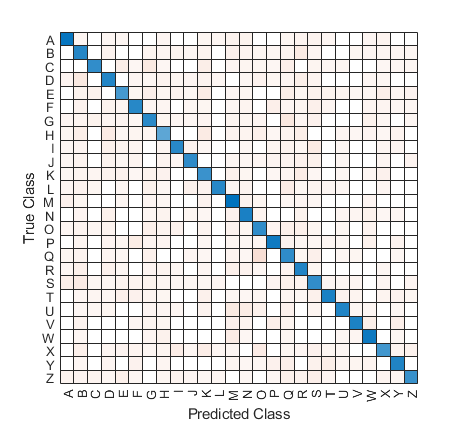

predictions = resubPredict(nBayes.nBayesModel);
confusionMat = confusionchart(categorical(Y), predictions);

[trainingLoss, testLoss] = nBayes.getModelLoss();
fprintf("Training loss: %0.02f Test loss: %0.02f, normalised dataset: %d\n", trainingLoss, testLoss, nBayes.dataset.isNormalised);

Training loss: 0.23 Test loss: 0.25, normalised dataset: 1


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.02f", totalTime);

Total cpu time (seconds): 7550.20

### Results

- Normalisation of the attributes has no effect.

- The kernal distribution is better than the normal distribution.

- The kernel width of 0.017277 is the best one when all attributes are used.

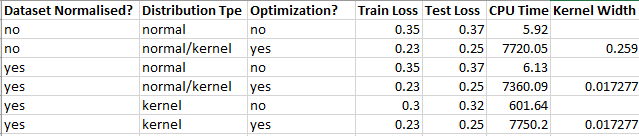

Based in these results, a final normalised, kernel run is performed on the **dataset with the highly correlated features removed.**

### Reduced Attribute Dataset Test Run

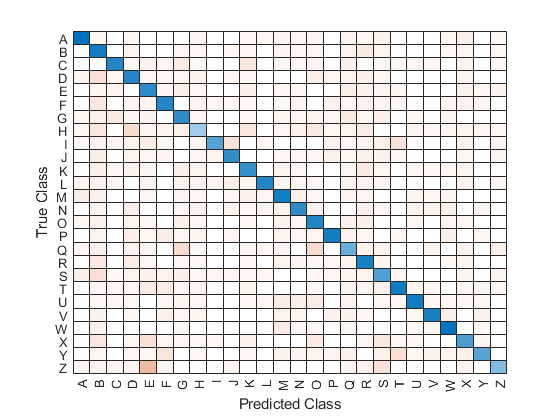


clear
clc
clf
close all
% loads the letter dataset into letterDatasetNormalised and
% 
load letterDatasetClass.mat
letterDataset = letterDatasetNormalised;
letterDataset.removeColumn("xBox");
letterDataset.removeColumn("yBox");
letterDataset.removeColumn("width");
letterDataset.removeColumn("height");
letterDataset.removeColumn("xEgvy");
[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);

startTime = cputime;
% get a kernel class
nBayes = NBayesClass.getKernelInstance(letterDataset);
model = nBayes.setPriorDistributionEmpirical();
predictions = resubPredict(model);
confusionMat = confusionchart(categorical(Y), predictions);


[trainingLoss, testLoss] = nBayes.getModelLoss();
fprintf("Training loss: %0.02f Test loss: %0.02f, normalised dataset: %d\n", ...
    trainingLoss, testLoss, nBayes.dataset.isNormalised);

Training loss: 0.31 Test loss: 0.32, normalised dataset: 1


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.02f", totalTime);

Total cpu time (seconds): 397.80

#### Try Optimization

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.34069 |      47.874 |     0.34069 |     0.34069 |       kernel |       0.0858 |


|    2 | Accept |     0.36606 |     0.44333 |     0.34069 |     0.35288 |       normal |            - |


|    3 | Accept |     0.36606 |     0.38245 |     0.34069 |     0.34069 |       normal |            - |


|    4 | Accept |     0.51931 |      47.795 |     0.34069 |     0.34069 |       kernel |      0.57441 |


|    5 | Best   |     0.25863 |      29.206 |     0.25863 |     0.25864 |       kernel |     0.020537 |


|    6 | Accept |     0.26319 |      29.645 |     0.25863 |      0.2586 |       kernel |     0.031007 |


|    7 | Best   |     0.25856 |      29.257 |     0.25856 |     0.25836 |       kernel |     0.016675 |


|    8 | Best   |     0.25856 |      29.148 |     0.25856 |     0.25845 |       kernel |     0.020467 |


|    9 | Best   |     0.25831 |      29.312 |     0.25831 |     0.25839 |       kernel |     0.019742 |


|   10 | Accept |     0.25856 |      28.894 |     0.25831 |     0.25839 |       kernel |     0.016708 |


|   11 | Accept |     0.25831 |      28.916 |     0.25831 |     0.25837 |       kernel |     0.019675 |


|   12 | Accept |     0.62769 |      46.042 |     0.25831 |     0.25838 |       kernel |      0.99995 |


|   13 | Accept |       0.259 |      29.194 |     0.25831 |     0.25841 |       kernel |     0.023041 |


|   14 | Accept |     0.44969 |      49.552 |     0.25831 |     0.25838 |       kernel |      0.20708 |


|   15 | Accept |     0.25875 |       30.74 |     0.25831 |     0.25845 |       kernel |     0.018403 |


|   16 | Accept |      0.2895 |      42.417 |     0.25831 |     0.25846 |       kernel |     0.051859 |


|   17 | Accept |     0.25856 |      29.101 |     0.25831 |     0.25846 |       kernel |     0.016673 |


|   18 | Accept |     0.27225 |       38.16 |     0.25831 |     0.25846 |       kernel |     0.039346 |


|   19 | Accept |     0.48363 |      50.609 |     0.25831 |     0.25846 |       kernel |      0.33789 |


|   20 | Accept |     0.39506 |      50.874 |     0.25831 |     0.25846 |       kernel |      0.12686 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|   21 | Accept |     0.26069 |      29.247 |     0.25831 |     0.25843 |       kernel |     0.026554 |


|   22 | Accept |      0.2585 |      29.003 |     0.25831 |     0.25843 |       kernel |     0.017552 |


|   23 | Accept |     0.25881 |      28.944 |     0.25831 |     0.25844 |       kernel |     0.021625 |


|   24 | Accept |      0.2585 |      28.938 |     0.25831 |     0.25845 |       kernel |     0.019078 |


|   25 | Accept |     0.31106 |      42.716 |     0.25831 |     0.25845 |       kernel |     0.065009 |


|   26 | Accept |     0.25931 |      28.947 |     0.25831 |     0.25845 |       kernel |     0.024349 |


|   27 | Accept |      0.2585 |      29.144 |     0.25831 |     0.25845 |       kernel |     0.017405 |


|   28 | Accept |      0.2585 |      28.633 |     0.25831 |     0.25845 |       kernel |     0.019354 |


|   29 | Accept |       0.266 |      36.589 |     0.25831 |     0.25845 |       kernel |     0.034483 |


|   30 | Accept |      0.2585 |       28.82 |     0.25831 |     0.25845 |       kernel |     0.017299 |


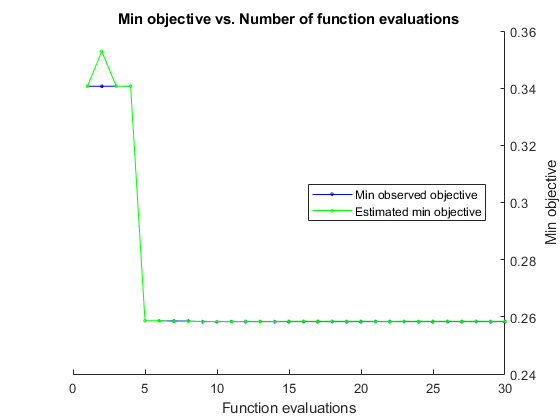

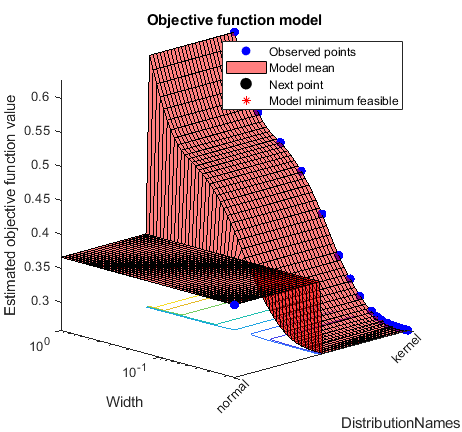


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 1003.1202 seconds
Total objective function evaluation time: 978.5416

Best observed feasible point:
    DistributionNames     Width  
    _________________    ________

         kernel          0.019742

Observed objective function value = 0.25831
Estimated objective function value = 0.25848
Function evaluation time = 29.3121

Best estimated feasible point (according to models):
    DistributionNames     Width  
    _________________    ________

         kernel          0.018403

Estimated objective function value = 0.25845
Estimated function evaluation time = 28.9467



obj =   NBayesClass with properties:

          randomSeed: 300
               debug: 1
             dataset: [1×1 LetterDatasetClass]
         nBayesModel: [1×1 ClassificationNaiveBayes]
                   x: [16000×11 table]
                   y: [16000×1 table]
                  xt: [4000×11 table]
                  yt: [4000×1 table]
    distNamesDefault: {'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'}
     distNamesKernel: {'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'}



nBayes = NBayesClass.getKernelInstance(letterDataset);
nBayes.fitMatlabHyperparameterOptimization();

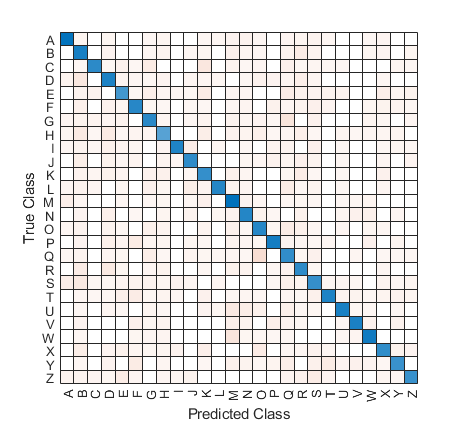


predictions = resubPredict(nBayes.nBayesModel);
confusionMat = confusionchart(categorical(Y), predictions);


[trainingLoss, testLoss] = nBayes.getModelLoss();
fprintf("Training loss: %0.02f Test loss: %0.02f, normalised dataset: %d\n", ...
    trainingLoss, testLoss, nBayes.dataset.isNormalised);

Training loss: 0.25 Test loss: 0.26, normalised dataset: 1


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.02f", totalTime);

Total cpu time (seconds): 5185.50

## Results Conclusion

The results from all the tests are below:

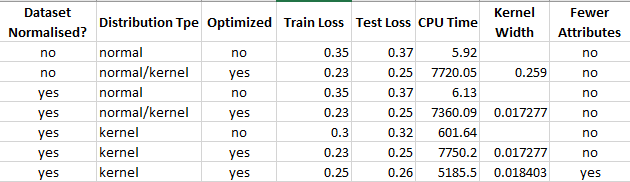

Conclusions drawn from the full dataset:

- Normalisation of the attributes has no effect.

- The kernal distribution is better than the normal distribution.

Conclusions drawn from using fewer features:

- Reducing the features has a very small effect on the training and test loss.

- The optimization task is quicker using fewer features (84 minutes versus 122 minutes cpu time).

- The optimized kernel width hyperparameter value is reported as 0.018493

Further work on the dataset should use the dataset with fewer features: the time reduction is great enough to justify the very small increase in loss of between 1% and 2%.